## SuperPoint

% Load the imported 3P model

savedModel = load("ajtracedmodel.mat")

savedModel = struct with fields:
    net: [1×1 dlnetwork]


net = savedModel.net

net =   dlnetwork with properties:

         Layers: [1×1 traced_model2.TopLevelModule]
    Connections: [0×2 table]
     Learnables: [24×3 table]
          State: [0×3 table]
     InputNames: {'TopLevelModule'}
    OutputNames: {'TopLevelModule/out1'  'TopLevelModule/out2'}
    Initialized: 0

  View summary with summary.


net = addInputLayer(net, imageInputLayer([480 640 1], Name="imageIn", Normalization="rescale-zero-one", Max=255, Min=0));
net = initialize(net)

net =   dlnetwork with properties:

         Layers: [2×1 nnet.cnn.layer.Layer]
    Connections: [1×2 table]
     Learnables: [24×3 table]
          State: [0×3 table]
     InputNames: {'imageIn'}
    OutputNames: {'TopLevelModule/out1'  'TopLevelModule/out2'}
    Initialized: 1

  View summary with summary.


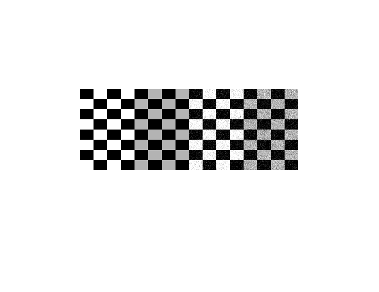

% I1 = im2gray(imread("parkinglot_left.png"));
% I2 = im2gray(imread("parkinglot_right.png"));
I1 = checkerboard(20);
I1 = imresize(I1, [480 640]);
I2 = checkerboard(20);
I2 = imnoise(I2,'gaussian');
I2 = imresize(I2, [480 640]);
montage([I1 I2])


joinedImages = cat(4, I1, I2);
X = dlarray(double(joinedImages), "SSCB");
% fakeImage = dlarray(rand(480, 640, 1,1), 'SSCB');
[points, descriptors] = predict(net, X);


% Process Points
% 1) Strip last dimension: `60(S)x80(S)x65(C)x1(B) -> 60(S)x80(S)x65(C)`
% Not sure if i need to strip last dimension
[interestPoints, heatmaps] = postProcessPoints(points);


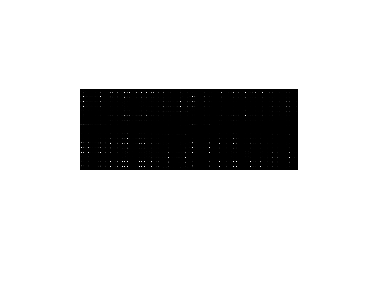

% Visualise the heatmap and interest points
rescaledHeatmap = extractdata(heatmaps) * 255;
montage([rescaledHeatmap(:,:,:,1) rescaledHeatmap(:,:,:,2)])

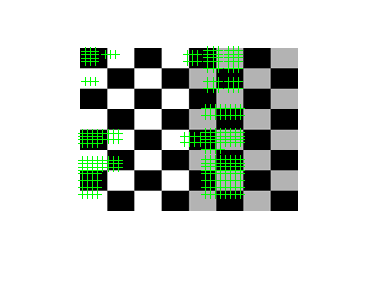


% Visualise keypoints
kp1 = interestPoints{1}(:,1:2);
kp2 = interestPoints{2}(:,1:2);
pts = cornerPoints(kp1);
imshow(I1);
hold on
plot(pts);
hold off

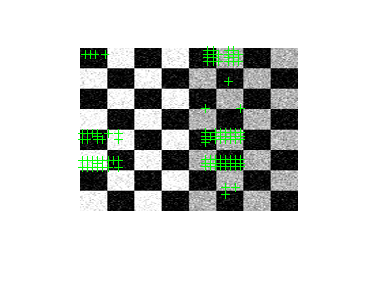


pts = cornerPoints(kp2);
imshow(I2);
hold on
plot(pts);
hold off